# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt');
% loading in the data from the csv matrix
converted_data = convert(data);
x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \mathrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_sigquared)

## 2 combine and calculate energy

sig_sig = S(x, y, z)';
mag_sigquared = abs(sig_sig).^2;
energy_sig = sum(mag_sigquared,"all","omitmissing","double")

The energy of S is obtained.

## 3 Implementation of moving average

showing the moving average working on the data below

plot_avgs(x)
plot_avgs(y)
plot_avgs(z)

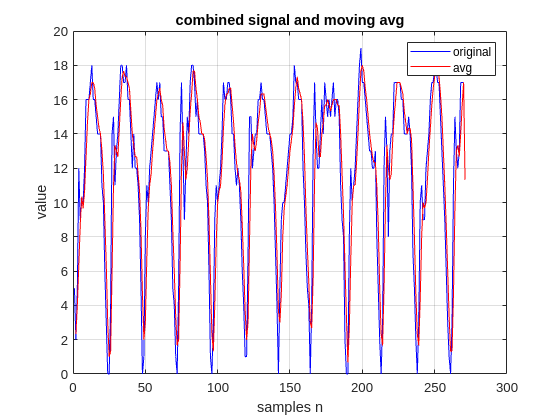

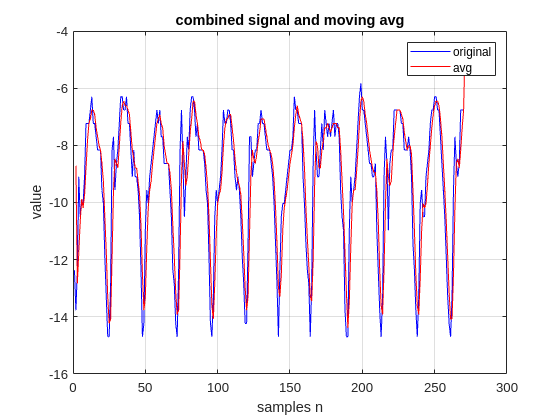

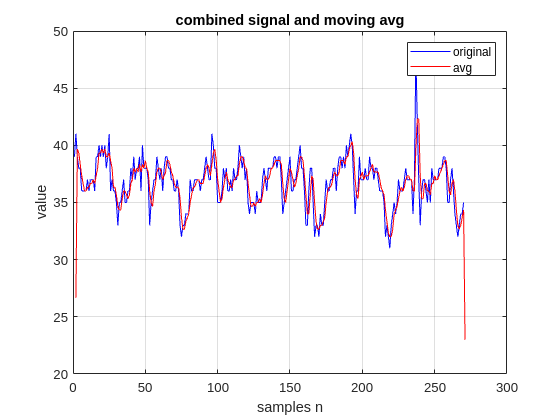

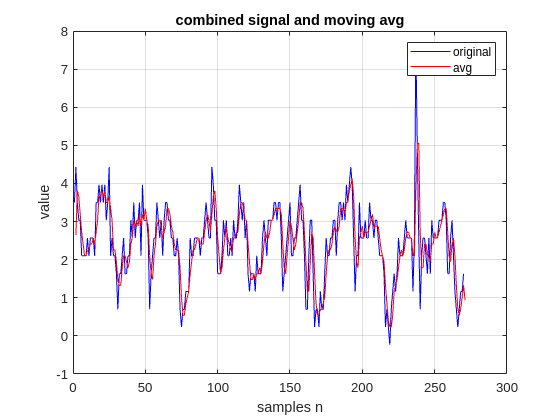

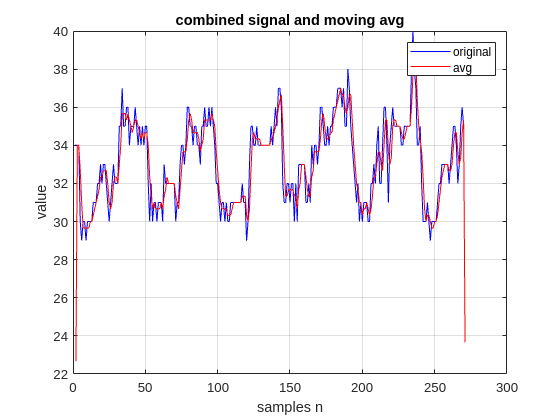

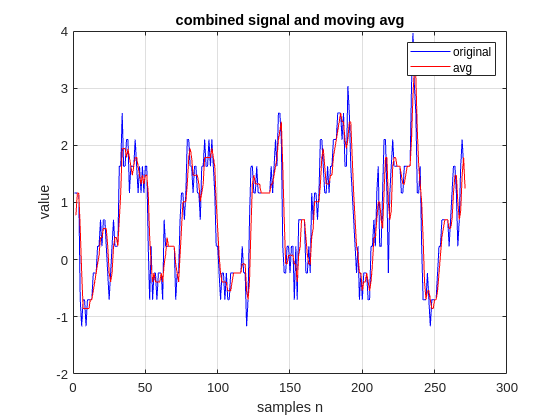

for i = 1:1:3
    figure
    plot_avgs(data(:,i))
    pause(.5)
    figure
    plot_avgs(converted_data(:,i))
    pause(.5)
end

## Here is the convolved impulse across the signals

impulse = 1;
conv_sig = conv(x,impulse);
hx = filter(impulse,1,x);
hy = filter(impulse,1,y);
hz = filter(impulse,1,z);
reg_range = (1:1:length(hx))';
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

## 4 Recursive system 1

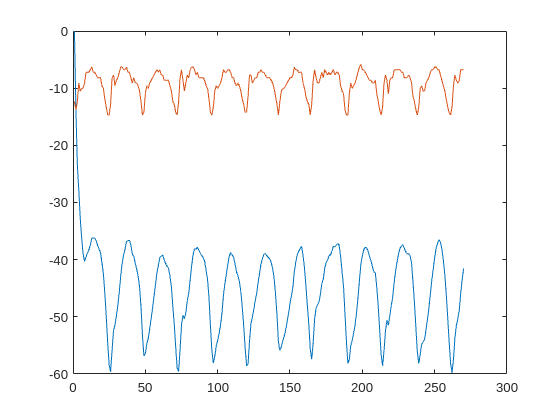

diff1_x = [diffeq1(x),x];
plot(diff1_x)

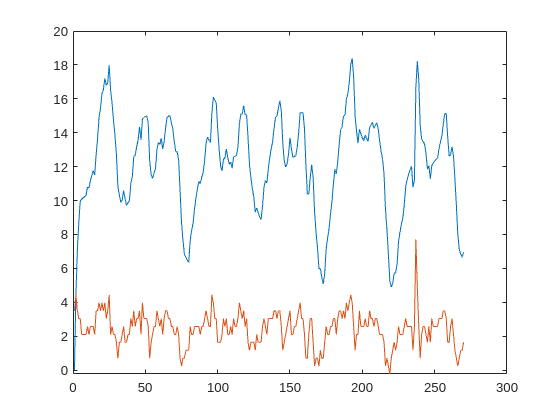


diff1_y = [diffeq1(y),y];
plot(diff1_y)

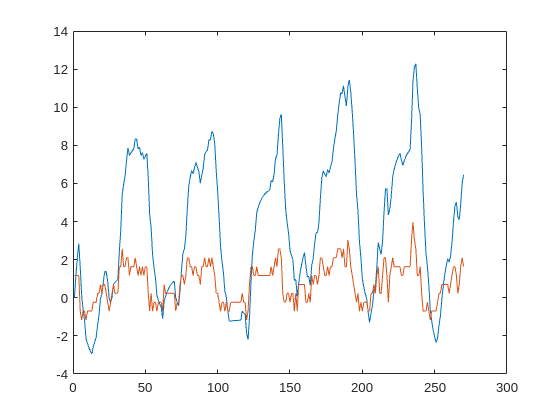


diff1_z = [diffeq1(z),z];
plot(diff1_z)

## 5 Recursive system 2

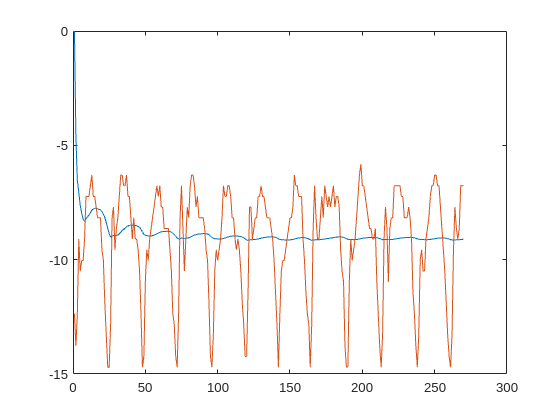

diff2_x = [diffeq2(x),x];
plot(diff2_x)

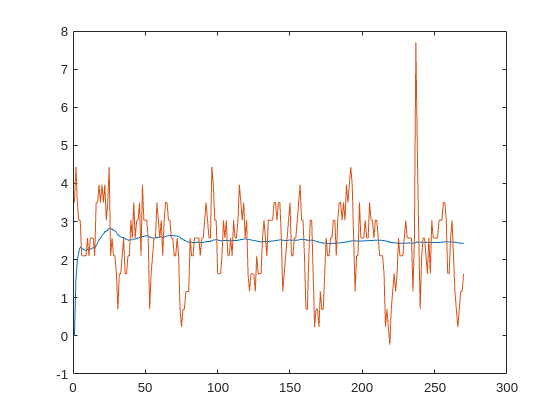


diff2_y = [diffeq2(y),y];
plot(diff2_y)

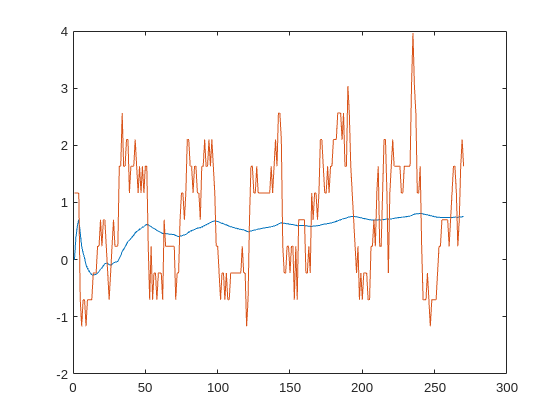


diff2_z = [diffeq2(z),z];
plot(diff2_z)

% This system is computing a cumulative average. I cannot remember the term mentioned in class, but we can see that the last value calculated 
% is one thatcounts toward the sum the least overall. same effect as having
% an average that you add one more value to, it is by definition a single
% value more than the average had increased by prior to this addition. the
% y term being multiplied by n shows that it must be first multiplied by
% the total number of elements that had been included thusfar.

## 6 Recursive system 3

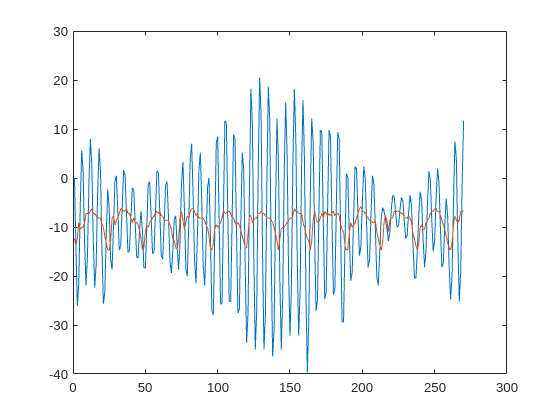

diff3_x = [diffeq3(x),x];
plot(diff3_x)

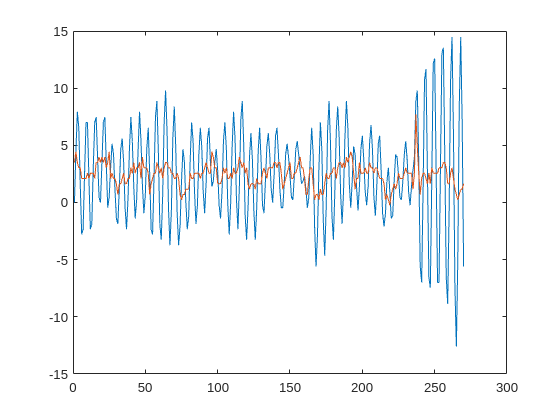


diff3_y = [diffeq3(y),y];
plot(diff3_y)

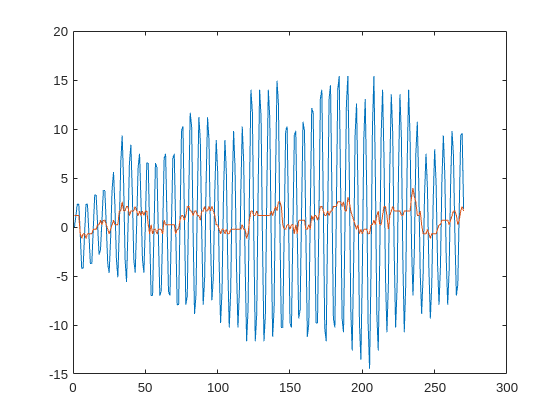


diff3_z = [diffeq3(z),z];
plot(diff3_z)

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

function plot_avgs(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
plot(1:1:length(x),x,'b',2:1:(length(conv_sig)-1),conv_sig(2:end-1),'r');
title('combined signal and moving avg')
xlabel('samples n')
ylabel('value')
grid on
legend('original','avg')
end

function crossCorr(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
hx = filter(avg_vec,1,x);
convX = conv(hx,x);
reg_range = (1:1:length(hx))';
new_range = -floor(length(convX)/2):1:floor(length(convX)/2);
figure()
plot(new_range,convX)
grid on
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with average and filter function')
legend("h_x","x","My_{avg}")
grid on
end

function y = diffeq1(x)
    y = zeros(size(x));
    y(1) = 0;
    for n = 2:length(x)
        y(n) = .8*(y(n-1)) + x(n);
    end
end

function y = diffeq2(x)
    y = zeros(size(x));
    y(1) = 0;
    for n = 2:length(x)
        y(n) = (n/(n+1))*y(n-1) + (1/(n+1))*x(n);
    end
end

function y = diffeq3(x)
    y = zeros(size(x));
    y(1) = 0;
    y(2) = y(1) + x(2);
    for n = 3:length(x)
        y(n) = y(n-1) - y(n-2) + x(n);
    end
end
